# Bit-to-complex-symbol mapping for IQ Modulations

This functions maps a bit stream into a complex symbol stream with respect to some IQ constellations.

**Inputs:**

- *bit_TX*: bit stream vector of size *nb_bit x 1*

- *nb_bit_per_symb*: number of bits per symbol

- *nb_bit*: number of bits in the input bit stream (= length of *bit_TX*)

**Ouputs:**

- *symb_TX*: complex symbol stream vector of size *nb_symb x 1* where *nb_symb = nb_bit / nb_bit_per_symb*

function symb_TX = mapping_QAM( bit_TX , nb_bit_per_symb , nb_bit )

if rem( nb_bit , nb_bit_per_symb ) ~= 0
    error('issue: the data stream is not an integer number of symbols')
end

nb_symb = nb_bit / nb_bit_per_symb ;                                % Number of symbols of the data stream
symb_TX = zeros( nb_symb , 1 ) ;                                    % Symbol stream vector initialization

## 4QAM constellation (<=> QPSK)

The mapping for the QPSK constellation should be done as shown below:

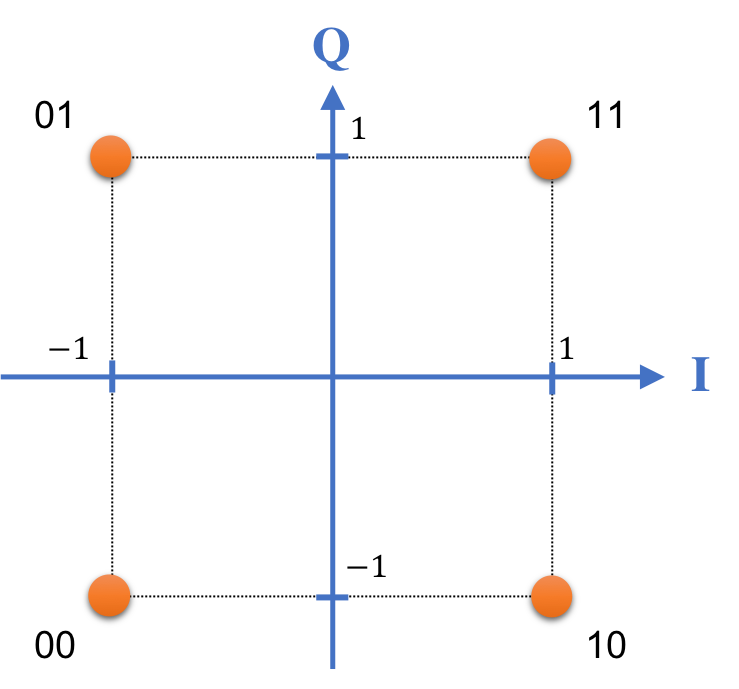

This mapping follows a gray coding: each symbol differs from its neighbors by one bit only. This reduces bit errors as a received symbol distorted by some noise is more likely to fall close to an adjacent symbol  than close to a faraway symbol. 

if nb_bit_per_symb == 2

    % QPSK mapping with Gray coding (vectorized)
    % Constellation from the figure:
    %   00 -> (-1,-1)    01 -> (-1,+1)
    %   10 -> (+1,-1)    11 -> (+1,+1)
    % bit 1 -> I component:  0 -> -1,  1 -> +1
    % bit 2 -> Q component:  0 -> -1,  1 -> +1

    I_map = [-1, +1] ;                                     % index 1->0, 2->1
    Q_map = [-1, +1] ;                                     % index 1->0, 2->1

    bit_matrix = reshape( bit_TX , 2 , nb_symb ).' ;       % nb_symb x 2
    idx_I = bit_matrix(:,1) + 1 ;                          % Binary to index (1-based)
    idx_Q = bit_matrix(:,2) + 1 ;
    symb_TX = I_map(idx_I).' + 1j*Q_map(idx_Q).' ;

end


## 16QAM constellation

The mapping for the 16QAM constellation should be done as shown below:

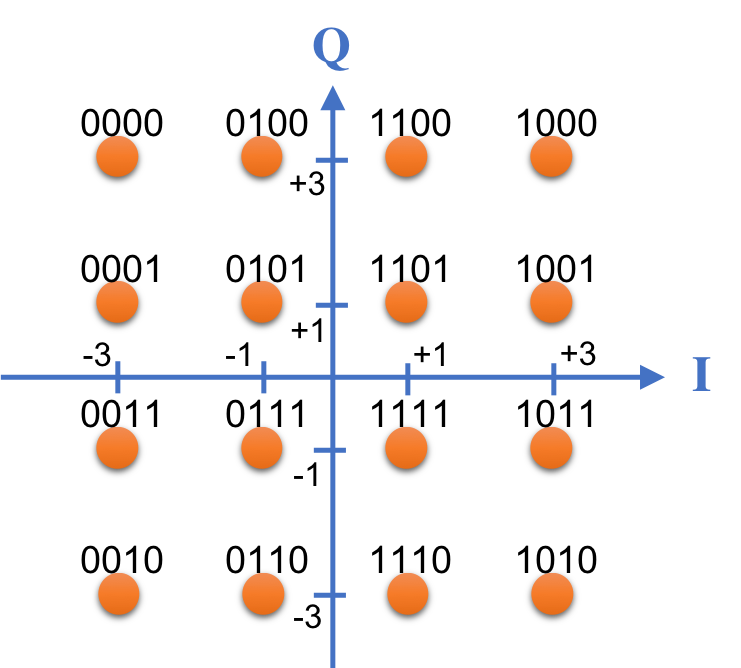

This mapping follows a gray coding: each symbol differs from its neighbors by one bit only. This reduces bit errors as a received symbol distorted by some noise is more likely to fall close to an adjacent symbol  than close to a faraway symbol. 

if nb_bit_per_symb == 4

    % 16QAM mapping with Gray coding (vectorized)
    % Constellation from the figure (b1 b2 -> I , b3 b4 -> Q):
    %   b1b2:  00 -> -3,  01 -> -1,  11 -> +1,  10 -> +3
    %   b3b4:  00 -> +3,  01 -> +1,  11 -> -1,  10 -> -3
    % Lookup tables indexed by binary value (b1*2+b2)+1

    I_map = [-3, -1, +3, +1] ;                  % index 1->00, 2->01, 3->10, 4->11
    Q_map = [+3, +1, -3, -1] ;                  % index 1->00, 2->01, 3->10, 4->11

    bit_matrix = reshape( bit_TX , 4 , nb_symb ).' ;       % nb_symb x 4
    idx_I = bit_matrix(:,1)*2 + bit_matrix(:,2) + 1 ;      % Binary to index (1-based)
    idx_Q = bit_matrix(:,3)*2 + bit_matrix(:,4) + 1 ;
    symb_TX = I_map(idx_I).' + 1j*Q_map(idx_Q).' ;

end

end